% Importing Square and Rectangle
    SquareImg = imread('square.jpg');
    RectImg = imread('rectangle.jpg');

% 5.2.10

% Need to create an image of any size. Cannot use built in matlab function 
% Creating Function for DST S matrix
function S= DST(n)
    % Creating a vector of 0's to allocate space
    S = zeros(n);
    % Creating for loop to create S matrix. Each cell will be equal to 
        % s_{i,j} = sqrt(2/n) * sin(pi*(i-1/2)*(j-1/2)/n)
    % Outer loop, which is rows
        for i = 1:n % Makes rows n large
            % Inner Loop, which is columns
            for j = 1:n
                % Setting the value of each cell via the DST function 
                S(i,j) = sqrt(2/n) * sin(pi*(i-1/2)*(j-1/2)/n);   
            end
        end
end

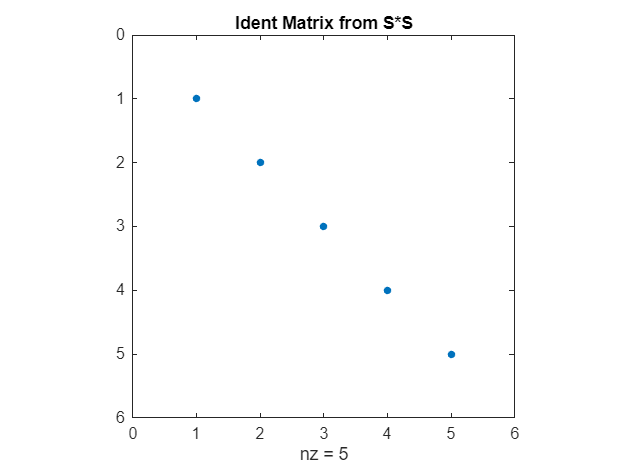

% 5.2.11

% Need to verify that a 5x5 S matrix S is equal to the inverse
% We can do this by showing that S * S = I

% Calling DST s matrix function with 5
    Matrix_Size = 5;
    S = DST(Matrix_Size);
% Will multiply S by S to ident matrix, then use spy to show the identity
% matrix
    S_ident = S * S;
% will round off S_ident so spy can show identity matrix
    f = figure(1);
    spy(round(S_ident,0))
    title('Ident Matrix from S*S')
% Export image as jpg
    exportgraphics(f, '5.2.11 Proof of S.jpg', 'Resolution', 300);     % high-DPI jpg    

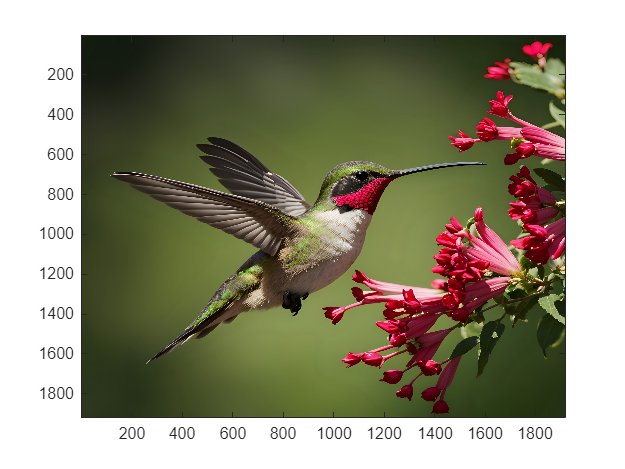

% 5.2.12
% Code form 5.1.1
% We need to determine what steps need to be taken to undo the 2
% Dimensional DST
   X = imread('square.jpg');
       imagesc(X)

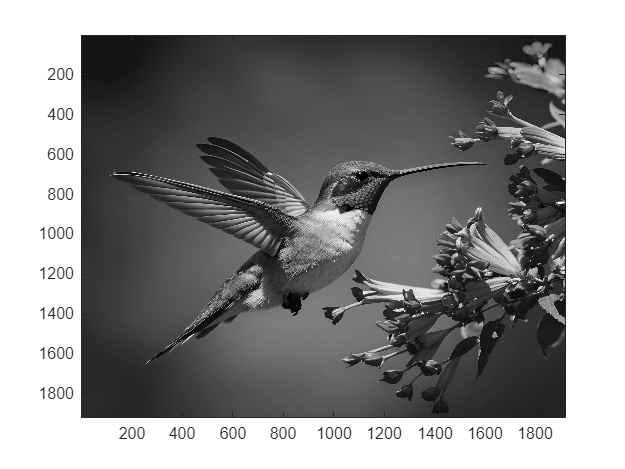

   % Convert X matrix to double datatype
       X_double = double(X);
       % Setting Variable that will be used in question below
           R = X_double(:,:,1);
           G = X_double(:,:,2);
           B = X_double(:,:,3);  
   % Convert to double (data type) greyscale image and read greyscale image 
       X_gray= X_double(:,:,1)/3.0 + X_double(:,:,2)/3.0 + X_double(:,:,3)/3.0;
           % Side note, this is taking the average of each intensity and
           % linearly combining it into 1 matrix
       %imagesc(uint8(X_gray))
       %colormap('gray') 
   % Set the size for our gray scale
           [m,n] = size(X_gray);
           S_m = DST(m);
           S_n = DST(n);
   % Create our original Function Y = S * X_g * S
       Y = S_m * X_gray * S_n;
   % Create our reconstructed Function
       X_gray_recon = S_m * Y * S_n;
   % Display both our Gray Scale and our Reconstructed Gray Scale
           figure(1);
           imagesc((X_gray))
           colormap('gray');

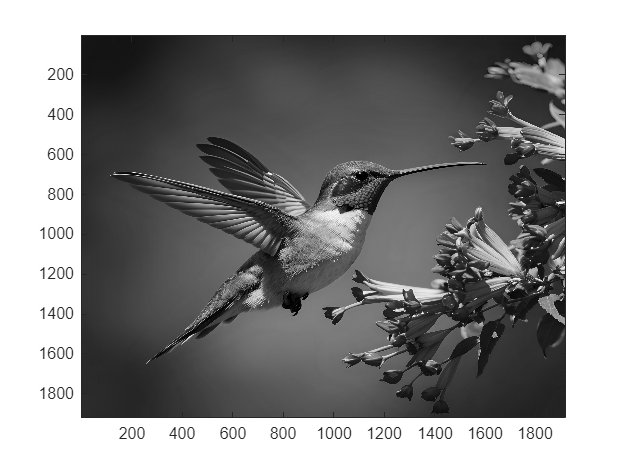



           figure(2);
           imagesc((X_gray_recon));
           colormap('gray'); 

   % Creating file images
        % Creating new Image
            imwrite(uint8(X_gray),'5.2.12_DST.jpg')
        % Creating new Image
            imwrite(uint8(X_gray_recon),'5.2.12_reconstruction.jpg')